Ali Saeizadeh - 810196477

# WLC CA - OFDM Implementation

## Part B: AWGN BER Plot

## Transmitter

#### Initilization & Generate Random Bits

cd 'F:\University\Semester IIX 2021\Wireless\Semester 2021\CA'
clear all; clc; close all;
wlc_init;
rng(1);
pkt_size = 10^7;
b_tx = bit_gen(pkt_size, k);
n_c = 400;
% num_sym_subcarrier = 30;
% num_frames = ceil(pkt_size / (n_c * num_sym_subcarrier))
sfc = ceil(2^13/n_c)

sfc = 21

num_sym_subcarrier = sfc

num_sym_subcarrier = 21

num_frames = ceil(length(b_tx) / (sfc * n_c))

num_frames = 1191

num_sym_frame = sfc * n_c

num_sym_frame = 8400

#### Generating Symbols

flg_gray_encode = 0;
if(flg_gray_encode == 1)
    b_code = gray_code(k);    
else
    b_code = non_code(k);
end 

sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
sym_idx = sym_idx - 1;
size(sym_idx)

ans =     10000000           1


#### QPSK Modulation

% [cons, Es_avg] = constellation(M, modulation)
% mod_sym = zeros(size(sym_idx));
% for i=1:size(sym_idx,1)
%     mod_sym(i,1) = cons(sym_idx(i,1));
% end
% mod_sym;

#### Frame Divider & Serial to Parallel

% Data = zeros([num_sym_subcarrier,n_c,num_frames]);
% size(Data)
% for i=1:num_frames-1
%     zero_pad_size = (num_sym_frame)- length(sym_idx)
% % sym_idx = [sym_idx; zeros((num_frames * num_sym_subcarrier * n_c) - length(sym_idx),1)];
% % Data = reshape(sym_idx,[num_sym_subcarrier,n_c,num_frames]);
% end

zero_pad_size = (sfc * num_frames * n_c) - length(sym_idx)

zero_pad_size = 4400

sym_idx = [sym_idx; zeros((num_frames * num_sym_subcarrier * n_c) - length(sym_idx),1)];
Data = reshape(sym_idx,[num_sym_subcarrier,n_c,num_frames]);
size(Data)

ans =           21         400        1191


#### Adding  Reference Row

ref_row = randi(4,1,size(Data,2),size(Data,3)) - 1;
Data1 = cat(1,ref_row, Data);

#### DPSK Modulation

Data2 = zeros(size(Data1));
Data2(1,:,:) = Data1(1,:,:);
for f = 2:num_sym_subcarrier + 1
    Data2(f,:,:) = mod(Data1(f - 1,:,:) + Data1(f,:,:), M);
end
Data2 = mod(Data2, M);

#### QPSK Signal Replacement

[cons, Es_avg] = constellation(M, modulation)

cons =    1.0000 + 0.0000i
   0.0000 + 1.0000i
  -1.0000 + 0.0000i
  -0.0000 - 1.0000i


Es_avg = 1

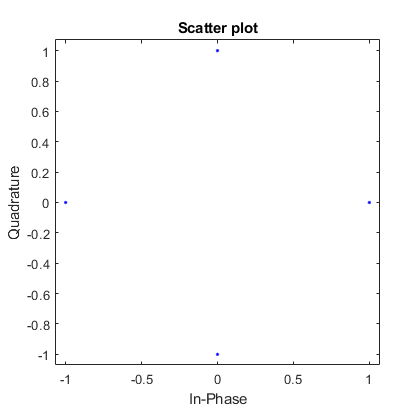

scatterplot(cons)

mod_sym = zeros(size(Data2));
for i=1:size(Data2,1)
    for j = 1:size(Data2,2)
        for k=1:size(Data2,3)
            mod_sym(i,j,k) = cons(Data2(i,j,k) + 1);
        end
    end
end
Data3 = mod_sym;

#### IFFT bins Allocation

Data4 = zeros(num_sym_subcarrier + 1, ifft_size, num_frames);
Data4(:,carriers,:) = Data3;
Data4(:,conj_carriers,:) = conj(Data3);

#### IFFT

ofdm_tx = zeros(size(Data4));
for i =1:num_frames
    ofdm_tx(:,:,i) = real(ifft(Data4(:,:,i),ifft_size,2));
end

#### Adding CP

end_symb = size(ofdm_tx, 2) 

end_symb = 1024

size(ofdm_tx(:,(end_symb-guard_time+1):end,:))

ans =           22         256        1191


ofdm_tx_cp = cat(2,ofdm_tx(:,(end_symb-guard_time+1):end,:), ofdm_tx);

#### Parallel to Serial

ofdm_tx_cp_serial = reshape(ofdm_tx_cp, size(ofdm_tx_cp,1)*size(ofdm_tx_cp,2),size(ofdm_tx_cp,3))

ofdm_tx_cp_serial =    -0.0273    0.0234   -0.0098    0.0312   -0.0156    0.0098    0.0156   -0.0313   -0.0176    0.0469   -0.0117    0.0039   -0.0078    0.0215    0.0020   -0.0098    0.0566    0.0137   -0.0059    0.0000    0.0078    0.0059    0.0195   -0.0059   -0.0176    0.0195    0.0293   -0.0000   -0.0098   -0.0117    0.0098    0.0176    0.0234    0.0078   -0.0020    0.0449    0.0156   -0.0371    0.0039    0.0293   -0.0215   -0.0176    0.0176    0.0352   -0.0156    0.0117    0.0156   -0.0059    0.0039    0.0234
    0.0313    0.0117   -0.0020    0.0059    0.0020    0.0273   -0.0547   -0.0117   -0.0039    0.0293   -0.0430    0.0234    0.0020   -0.0117   -0.0137   -0.0371    0.0078   -0.0020   -0.0098    0.0234    0.0137   -0.0039    0.0137   -0.0293   -0.0215   -0.0059    0.0332   -0.0273   -0.0352    0.0195    0.0098   -0.0156    0.0352   -0.0469    0.0000    0.0098    0.0605   -0.0723   -0.0098    0.0098   -0.0176    0.0195   -0.0059   -0.0000    0.0742   -0.0039   -0.0195    0.005

size(ofdm_tx_cp_serial)

ans =        28160        1191


SNR = 20:50

SNR =     20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


ber_awgn = zeros(size(SNR));

## Channel

#### Clipping

for s=1:length(SNR)
clipping = 3;
clipped_peak = (10^(0-(clipping/20)))*max(abs(ofdm_tx_cp_serial));
ofdm_tx_cp_serial_clipped = ofdm_tx_cp_serial;
for i=1:1:size(ofdm_tx_cp_serial,2)
    ofdm_tx_cp_serial_clipped(abs(ofdm_tx_cp_serial_clipped(:,i))>=clipped_peak(i),i) = clipped_peak(i) .* ofdm_tx_cp_serial_clipped(abs(ofdm_tx_cp_serial_clipped(:,i))>=clipped_peak(i), i) ./ abs(ofdm_tx_cp_serial_clipped(abs(ofdm_tx_cp_serial_clipped(:,i))>=clipped_peak(i),i));
end

#### AWGN Channel

SNR_dB = SNR(s);
ofdm_rx_cp_serial = ofdm_tx_cp_serial_clipped;
Eb =  Es_avg/log2(M);
EbNo = db2pow(SNR_dB);
var_noise = (Eb ./ EbNo);
mean_noise = 0;
noise_smpl = sqrt(var_noise/2) .* (randn(size(ofdm_rx_cp_serial)) + 1i * randn(size(ofdm_rx_cp_serial))) + mean_noise;
% noise_smpl = sqrt(var_noise) .* (randn(size(ofdm_rx_cp_serial)) + mean_noise);
ofdm_rx_cp_serial = ofdm_rx_cp_serial + noise_smpl;

## Reciever

Serial to Parallel

ofdm_rx_cp_parallel = reshape(ofdm_rx_cp_serial,[floor(size(ofdm_rx_cp_serial,1)/(ifft_size + guard_time)), ifft_size + guard_time, num_frames]);

CP Removal

ofdm_rx_parallel = ofdm_rx_cp_parallel(:,guard_time + 1:end,:);

FFT

rx_carriers_bins = zeros(size(ofdm_rx_parallel));
for i =1:num_frames
    rx_carriers_bins(:,:,i) = fft(ofdm_rx_parallel(:,:,i),ifft_size,2);
end

Extract Carriers from FFT bins

rx_carriers = rx_carriers_bins(:,carriers,:);

DPSK Demodulation

[cons, Es_avg] = constellation(M, modulation);
ofdm_cons = reshape(cons,1,1,1,4);
[det_sym] = min_dist_detector(rx_carriers, cons);
similarity = det_sym == (ofdm_cons);
[v,det_sym_idx] = max(similarity,[],4);
det_sym_idx = det_sym_idx - 1;


demod_rx = zeros(size(det_sym_idx));
% demod_rx(1,:,:) = det_sym_idx(1,:,:);
demod_rx(1,:,:) = ref_row;

for i=2:num_sym_subcarrier + 1
    demod_rx(i,:,:) = mod(det_sym_idx(i,:,:) -  demod_rx(i-1,:,:),M);
end

demod_rx = demod_rx(2:end,:,:);

Parallel to Serial

data_rx = demod_rx;
% size(data_rx)
% for i = 1:num_frames
%     data_rx(:,:,i) = demod_rx(1,1:sfc,i);
% end
demod_rx_serial = reshape(data_rx,size(data_rx,1)*size(data_rx,2)*size(data_rx,3),1);
det_rx_serial = demod_rx_serial(:,1);

Estimated Output

det_rx_serial = mod(det_rx_serial,M);
det_bit = b_code(det_rx_serial + 1,:);
det_bit = det_bit(1:end - zero_pad_size,:);

BER Cal

ber_awgn(s) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
end

BER Plot

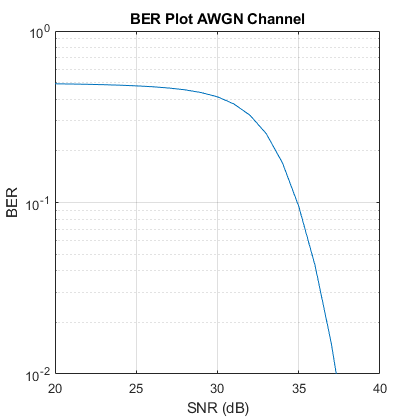

semilogy(SNR,ber_awgn)
grid on
title('BER Plot AWGN Channel')
ylabel('BER')
xlabel('SNR (dB)')
ylim([1e-2 1])

save('ber_awgn.mat',"ber_awgn")